# Example 4.1: The effects of filtering with and without padding.

This example is from *Digital Image Processing Using MATLAB*, 3rd edition, by Rafael C. Gonzalez, Richard E. Woods, and Steven L. Eddins, Gatesmark Press, 2020. 

This example may use functions, images, and other data that are included with the book. For instructions on obtaining this material, or for other information about the book, visit [imageprocessingplace.com](http://imageprocessingplace.com/DIPUM-3E/dipum3e_main_page.htm).

Copyright 2020-2021, Gatesmark Press

We use the image in Fig. 4.5(a) to illustrate the difference between filtering with and without padding. In the following discussion we use the custom function lpfilter to generate a Gaussian lowpass filter transfer function similar to Fig. 4.4(b), whose shape is determined by its standard deviation (sig). We will introduce this function in Section 4.5, but its syntax is straightforward, so we use it here and defer further explanation of lpfilter to that section. 					

The following commands perform filtering without padding: 			

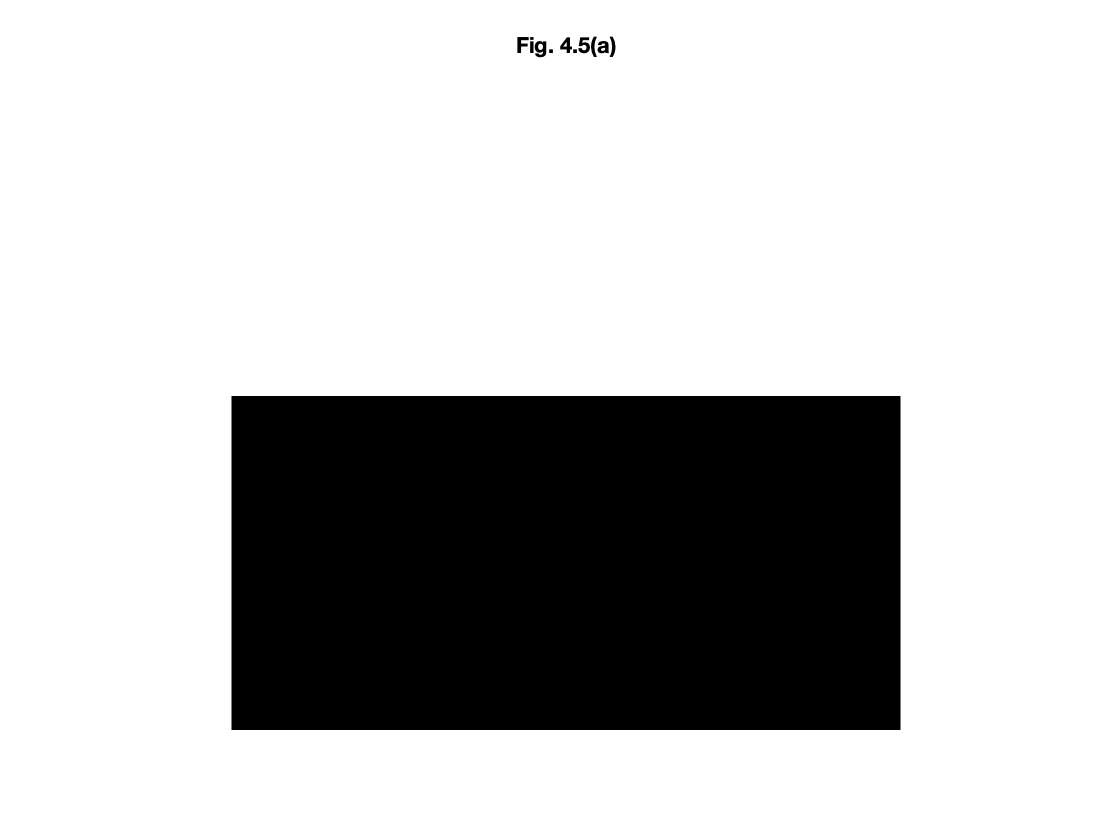

f = imread('two-stripes.tif');
figure, imshow(f), title('Fig. 4.5(a)')

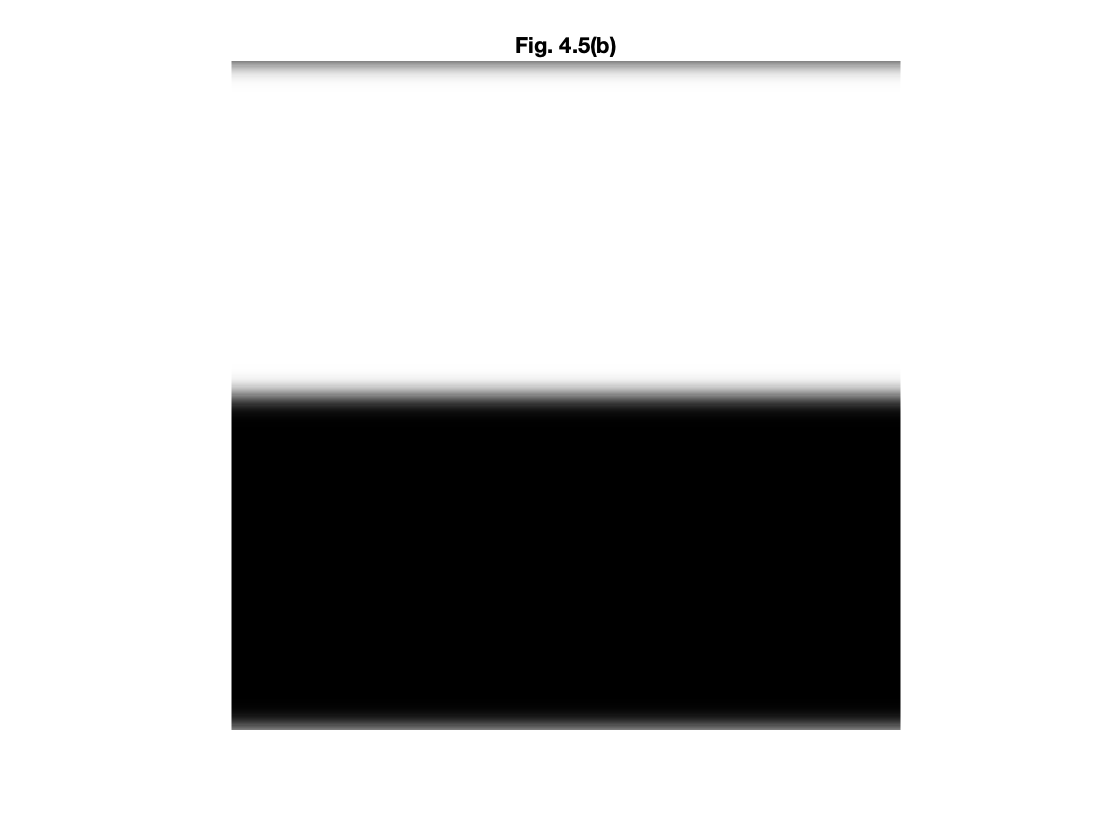

[M,N] = size(f);
[f,revertClass] = tofloat(f);
F = fft2(f);
sig = 10;
H = lpfilter('gaussian',M,N,sig);
G = H.*F;
g = ifft2(G);
g = revertClass(g);
figure, imshow(g), title('Fig. 4.5(b)')

Figure 4.5(b) shows the filtered image, g. As expected, the image is blurred, but note that the vertical edges are not. We can explain the reason using Fig. 4.6(a), which shows graphically the implied periodicity in DFT computations. The thin white lines between the images are included for clarity in viewing; they are not part of the data. The dashed lines are used to designate the *M *× *N *image processed by `fft2`. Imagine convolving a blurring filter with this infinitely periodic sequence. When the filter is passing through the top of the dashed image it will encompass part of the image itself and also the bottom part of the periodic component immediately above it. Thus, when a light and a dark region reside under the filter, the result will be a mid-gray, blurred output. This is what the top of the image in Fig. 4.5(b) shows. On the other hand, when the filter is on a side of the dashed image, it will encounter an identical region in the periodic component adjacent to the side. Because the average of a constant region is the same constant value, there is no blurring in this part of the result. Other parts of the image in Fig. 4.5(b) are explained in a similar manner. 				

Consider now filtering with padding: 				

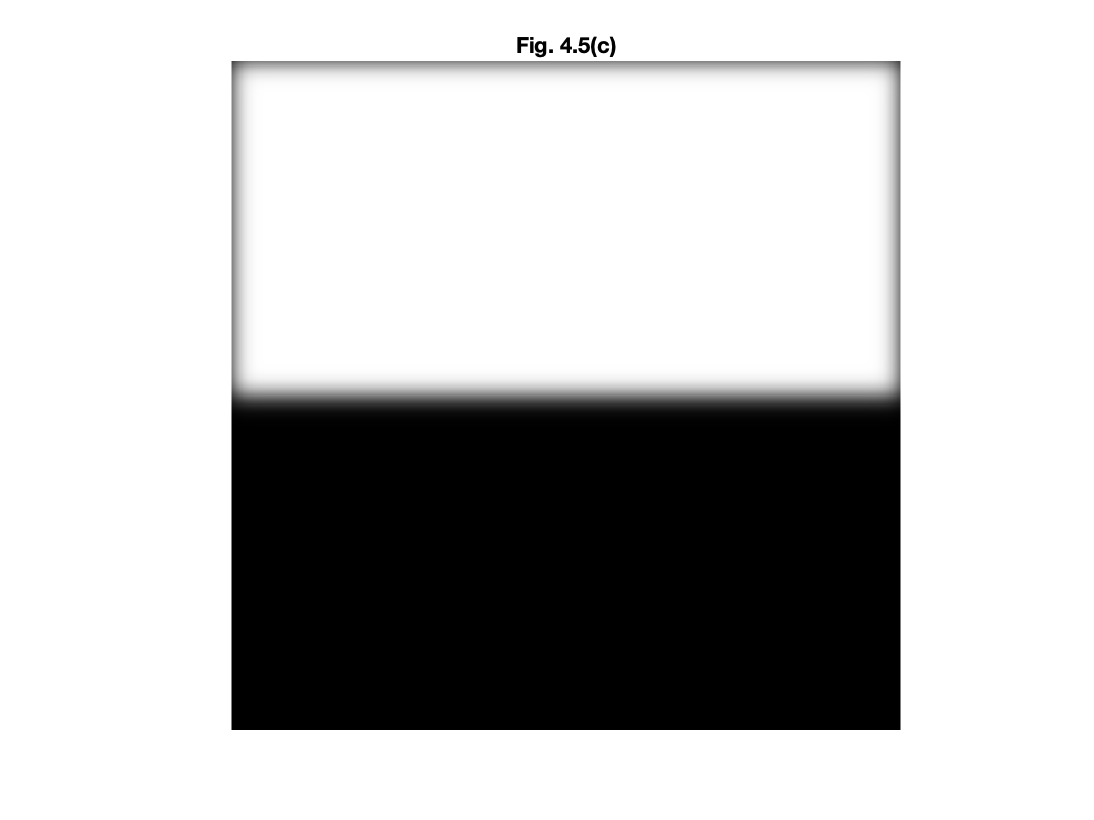

PQ = paddedsize(size(f)); % f is floating point.
Fp = fft2(f,PQ(1),PQ(2)); % Compute the FFT with zero padding.
Hp = lpfilter('gaussian',PQ(1),PQ(2),2*sig);
Gp = Hp.*Fp;
gp = ifft2(Gp);
gpc = gp(1:size(f,1),1:size(f,2));
gpc = revertClass(gpc);
figure, imshow(gpc)
title('Fig. 4.5(c)')

where we used `2*sig` because the size of the filter transfer function is now twice the size used without padding. 

### Figure 4.6

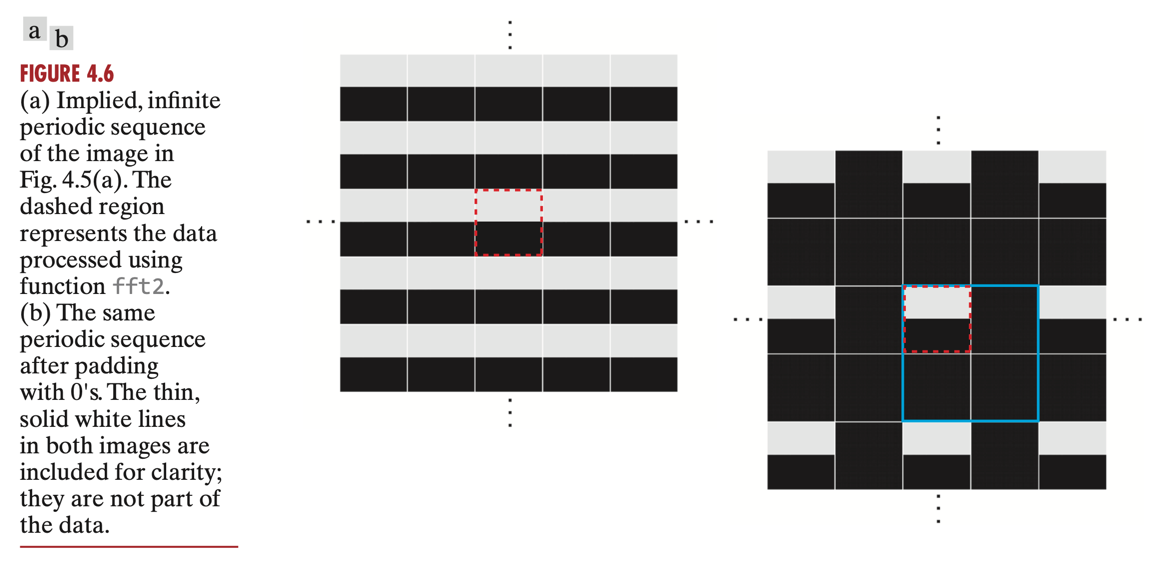

Figure 4.7 shows the full, padded filtered result, `gp`. The final result in Fig. 4.5(c) was obtained by cropping Fig. 4.7 to the original image size (see the sixth command in the preceding code). This result can be explained with the aid of Fig. 4.6(b), which shows the dashed image padded with zeros (black) as it would be set up in `fft2(f,PQ(1),PQ(2))` prior to computing the DFT. The implied periodicity is as explained earlier. The image now has a uniform black border all around it, so convolving a smoothing filter with this infinite sequence would show a gray blur in all light edges of the image.